# RVC Toolbox + Matlab native function

A robot can be defined by mean of a mathematical model described by omogeneous transformation matrices that are build following the so called Denavit-Hartenberg (DH) convention. 

Those matrices can be obtained in two different ways:

- Using the **native matlab function** *se(2)* (2D planar robot) or *se(3)* (3D robot).

- Using the **RVC Toolbox**: ETS2 or ETS3

## Example 1) 2D ROBOT

Suppose we would like to model the robot in the following figure:

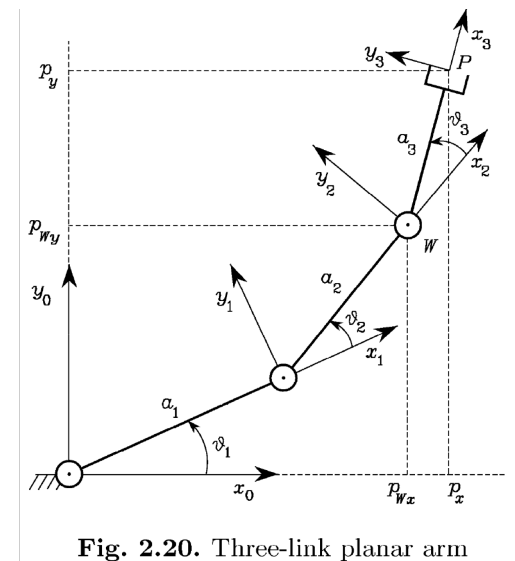

and obtain is direct kinematic that we know to be:

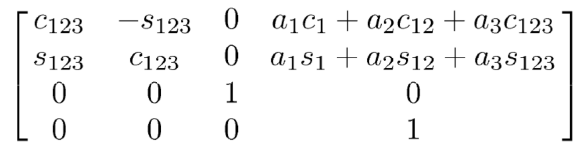

syms theta1 theta2 theta3 a1 a2 a3
cos123 = cos(theta1+theta2+theta3);
sin123 = sin(theta1+theta2+theta3);
T_reference = [cos123 -sin123 0 a1*cos(theta1)+a2*cos(theta1 + theta2)+a3*cos123;
               sin123 cos123 0 a1*sin(theta1)+a2*sin(theta1 + theta2)+a3*sin123;
               0 0 1 0;
               0 0 0 1]; 
T_reference = double(subs(T_reference,[theta1 theta2 theta3 a1 a2 a3],[deg2rad(20)*ones(1,3) ones(1,3)]));

T_reference =     0.5000   -0.8660         0    2.2057
    0.8660    0.5000         0    1.8508
         0         0    1.0000         0
         0         0         0    1.0000


### Using RVC Toolbox

a1 = 1;
link1 = ETS2.Rz("q1")*ETS2.Tx(a1)

 
link1 = 
Rz(q1)Tx(1)


a2 = 1;
link2 = ETS2.Rz("q2")*ETS2.Tx(a2)

 
link2 = 
Rz(q2)Tx(1)


a3 = 1;
link3 = ETS2.Rz("q3")*ETS2.Tx(a3)

 
link3 = 
Rz(q3)Tx(1)


R = link1*link2*link3

 
R = 
Rz(q1)Tx(1)Rz(q2)Tx(1)Rz(q3)Tx(1)


Once we have modelled all the links/joints relation we can use the command *fkine([<angle in rad>])* on the object* R *to obtain the direct/forward kinematics of the joint

T = R.fkine(deg2rad(20*ones(3,1)))

T =     0.5000   -0.8660    2.2057
    0.8660    0.5000    1.8508
         0         0    1.0000


### Using Matlab native functions

Equvalently we can use the matlab native function 

link1_ = se2(deg2rad(20),"theta")*se2(eye(2),[a1 0]);
link2_ = se2(deg2rad(20),"theta")*se2(eye(2),[a2 0]);
link3_ = se2(deg2rad(20),"theta")*se2(eye(2),[a3 0]);

T_ = link1_*link2_*link3_

T_ = se2
    0.5000   -0.8660    2.2057
    0.8660    0.5000    1.8508
         0         0    1.0000


Usign the command *printtform2d()* I can retrive the position and the angle of the end effector with respect the base reference system  

printtform2d(se2(T),unit="deg")

t = (2.21, 1.85), 60 deg


If I want a graphical representation of the 2D robots I can use the command *teach. *This command allow me to get the 2D position of the end-effector and the angle respect to the base reference system. With the slider in the figure I can modify the angle of the joints modifying also the configuration of the robot.   

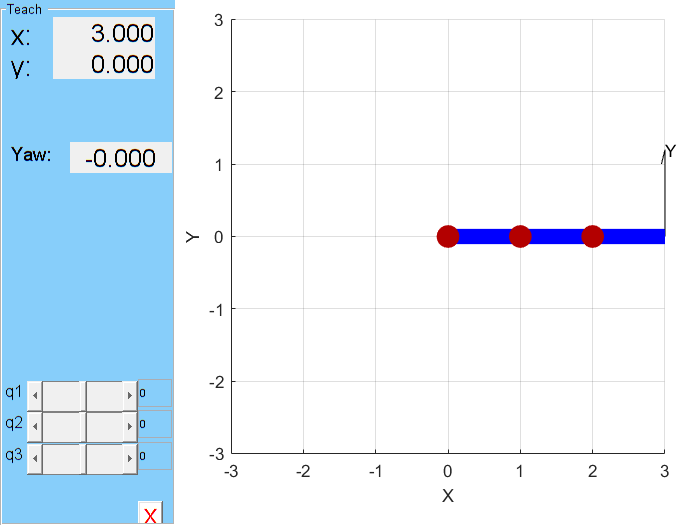

R.teach